# **Ejercicio 2**

## T6_7E2. Primeras derivadas parciales

clear, clc % Limpieza del entorno de trabajo

a) Escribe una función en Matlab que evalúe las primeras derivadas

parciales$\frac{\partial }{\partial x}f,\frac{\partial }{\partial y}f$ ( de una función 𝑓(𝑥, 𝑦) dada por puntos tabulados discretos con igual espaciado. Utiliza fórmulas de diferencia central de dos puntos en los puntos interiores y fórmulas de diferencia de tres puntos hacia delante y hacia atrás en los puntos extremos.

- Véase PrmDerPar.m

b) Los siguientes datos de la componente (𝑢) de la velocidad en la dirección 𝑥, se obtienen en función de las dos coordenadas 𝑥 e 𝑦:

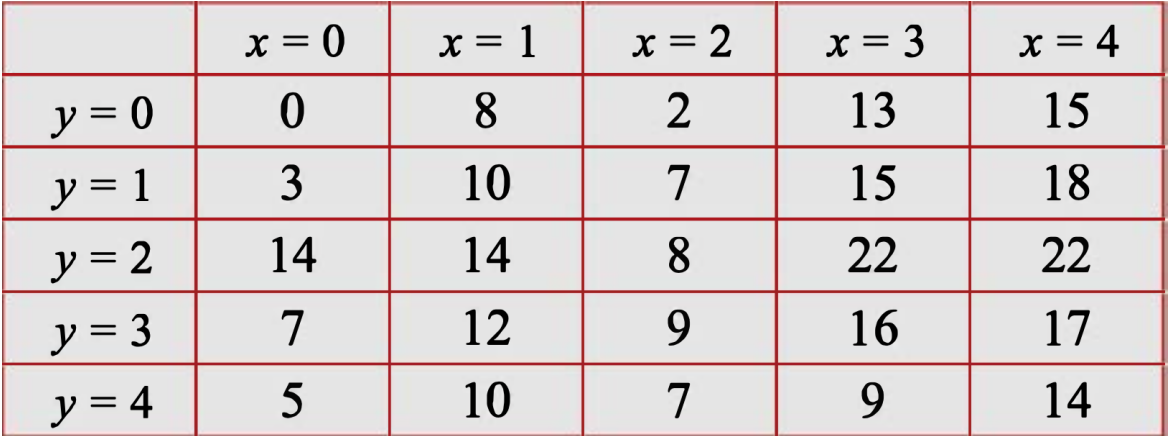

la posición $\left(i,j\right)$ de la matriz de resultados es la derivada en el punto que corresponde a $u\left(x\left(i\right),y\left(j\right)\right)$

x = 0:1:4;
y = 0:1:4;
u = [0 8 2 13 15;
    3 10 7 15 18;
    14 14 8 22 22;
    7 12 9 16 17;
    5 10 7 9 14]

u =      0     8     2    13    15
     3    10     7    15    18
    14    14     8    22    22
     7    12     9    16    17
     5    10     7     9    14


Trabajaremos con x en filas e y en columnas

u = u';

Emplea la funcion `PrmDerPar para calcular las derivadas parciales de u: `$\frac{\partial u}{\partial x},\;\frac{\partial u}{\partial y}$

[dudx,dudy] = PrmDerPar(x, y, u);
disp("Derivada parcial respecto de x:")

Derivada parcial respecto de x:


disp(dudx)

   -1.0000    7.0000    2.0000   -4.5000    0.5000
    1.0000    3.0000    1.0000   -2.0000   -2.0000
    7.0000    3.0000    1.0000   -0.5000   -3.5000
   -0.5000    4.5000    0.5000   -6.5000   -7.5000
    2.5000    3.5000   -0.5000   -4.0000   -2.0000




disp("Derivada parcial respecto de y:")

Derivada parcial respecto de y:


disp(dudy)

   15.0000   12.0000    3.0000    9.0000    9.0000
    1.0000    2.0000   -3.0000    1.0000    1.0000
    2.5000    2.5000    4.0000    2.0000   -0.5000
    6.5000    5.5000    7.0000    4.0000    3.5000
   -2.5000    0.5000   -7.0000   -2.0000    6.5000

